figure('Position', [0, 0, 320, 320], 'Renderer', 'opengl');
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

tab10 = [
        31, 119, 180;
        255, 127, 14;
        44, 160, 44;
        214, 39, 40;
        148, 103, 189;
        140, 86, 75;
        227, 119, 194;
        127, 127, 127;
        188, 189, 34;
        23, 190, 207
    ] / 255;

test_idx = 47

test_idx = 47

% dataCell = cell(1, 2); 
% data_ls = [50, 70];
% result_50 = readmatrix('data/height50_data.csv');
% for i = 1:2
%     filename = sprintf('height%d_data.csv', data_ls(i));
%     dataCell{i} = readmatrix(filename);
% end
% 
% test_GUs = dataCell{1}(test_idx,1:12);
% gnd = reshape(test_GUs, [3, 4]);  % 3×4 행렬 (각 열: [x; y; z])
% uav_pos1 = dataCell{1}(test_idx,13:15); 
% uav_pos2 = dataCell{2}(test_idx,13:15);

% ax = axes('Projection', 'perspective');
% 
% plotScene(ax, 'mesh_', 0:4, gnd, uav_pos1, [-100,100], [-100,100], [0,100], [30,45]);
% title(ax, 'height=50, az=30, el=45');
% exportgraphics(gcf, 'high_res_figure.eps', 'Resolution', 2400);
% exportgraphics(gcf, 'high_res_figure.png', 'Resolution', 2400);


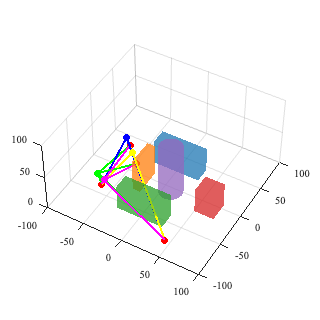

test_data = readmatrix('data/test_50.csv');

test_GUs = test_data(test_idx,1:12);
gnd = reshape(test_GUs, [3, 4]);  % 3×4 행렬 (각 열: [x; y; z])
bf = test_data(test_idx,13:15);
prob = test_data(test_idx,16:18);
cent = test_data(test_idx,19:21);
dl = test_data(test_idx,22:24);

ax = axes('Projection', 'perspective');
plotScene(ax, 'mesh_', 0:4, gnd, bf, prob, cent, dl, [-100,100], [-100,100], [0,100], [30,45]);

exportgraphics(gcf, 'high_res_figure_2.png', 'Resolution', 2400);